clear
clc

Symbolic Variables

syms x y z phi theta psi x_dot y_dot z_dot phi_dot theta_dot psi_dot
syms x_ddot y_ddot z_ddot phi_ddot theta_ddot psi_ddot
syms p q r p_dot q_dot r_dot
syms w1 w2 w3 w4

syms m g l kf km Ix Iy Iz

State

X = [x y z phi theta psi x_dot y_dot z_dot phi_dot theta_dot psi_dot];

Input

U = [w1 w2 w3 w4];

Drone Parameters

m = 0.027; % kg
g = 9.81; % m / s ^2
l = 0.046; % m
Ix = 1.66e-5; % kg m ^2
Iy = 1.66e-5; % kg m ^2
Iz = 2.93e-5; % kg m ^2

I = blkdiag(Ix, Iy, Iz);
inv_I = blkdiag(1 / Ix, 1 / Iy, 1 / Iz);

kf = 2.2e-8; % kg m / rad^2
km = 2e-9;

State Space

state_space_data = load('D:\CMU\Fall 2021\Advanced Contol Systems Integration\Project\Drone Simulation\State_Space.mat');
state_space = state_space_data.state_space;
A = state_space(:, 1:12);
B = state_space(:, 13:16);

Equilibrium Point

Hover State

x_hover = zeros(1, 12);
x_hover(3) = 1;

Hover Speed

w_hover = sqrt(m * g / (4 * kf));

Hover Input

u_hover = w_hover * ones(1, 4);

Equilibrium State Space

A_hover = double(subs(A, [X, U], [x_hover, u_hover]))

A_hover =          0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0         0         0         0    1.0000
         0         0         0         0    9.8100         0         0         0         0         0         0         0
         0         0         0   -9.8100         0         0         0         0         0         0         0         0
         0         0  

B_hover = double(subs(B, [X, U], [x_hover, u_hover]))

B_hover =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.0028    0.0028    0.0028    0.0028
         0    0.2115         0   -0.2115


LQR

Q = diag([7.5, 7.5, 7.5, 1, 1, 1, 1, 1, 1, 1, 1, 1]);
R = diag(0.001*ones(size(U, 2), 1));
K = lqr(A_hover, B_hover, Q, R);

save('D:\CMU\Fall 2021\Advanced Contol Systems Integration\Project\Drone Simulation\Gain Matrix.mat', "K")

Simulation Setup

x_T = zeros(12, 1);
x_T(1, 1) = 0;
x_T(2, 1) = 0;
x_T(3, 1) = 0.5;

x_0 = zeros(12, 1);
x_0(3, 1) = 0.0;

u_0 = u_hover';

Time Horizon and Timesteps

T = 10;
h = 0.01;
k = (T / h) + 1;

Forward Rollout

X_traj = zeros(size(x_0, 1), k);
X_traj(:, 1) = x_0;

U_traj = repmat(u_0, 1, k - 1);

for i = 1:k - 1
    x_k = X_traj(:, i);
    e_k = x_k - x_T;
    u_k = U_traj(:, i) + (-K * e_k);
    x_k1 = Drone_Dynamics_RK4(x_k, u_k, h);
    
    X_traj(:, i + 1) = x_k1;
    U_traj(:, i) = u_k;
end
disp(X_traj(1:3, end))

   -0.0000
   -0.0000
    0.5028



norm((X_traj(1:3, end) - x_T(1:3, 1)), 2)

ans = 0.0028

Plots

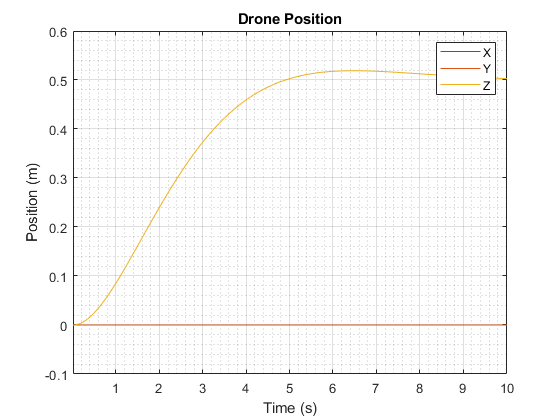

plot(1:k, X_traj(1:3, 1:end))
title('Drone Position')
xlabel('Time (s)')
ylabel('Position (m)')
xlim([1, k])
xticklabels(linspace(1, T, T))
legend('X', 'Y', 'Z')
grid on
grid minor

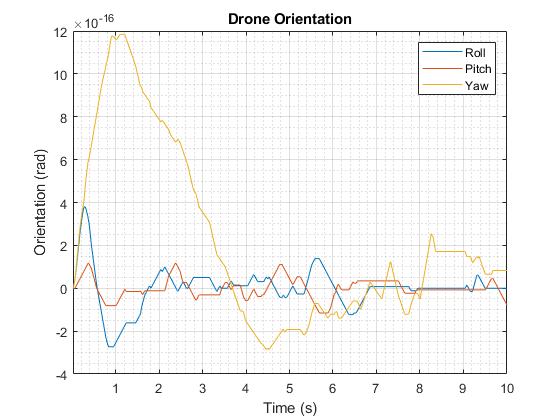

plot(1:k, X_traj(4:6, :))
title('Drone Orientation')
xlabel('Time (s)')
ylabel('Orientation (rad)')
xlim([1, k])
xticklabels(linspace(1, T, T))
legend('Roll', 'Pitch', 'Yaw')
grid on
grid minor

Functions

function RotMat = rpy2rot(r, p, y)
    cos_r = cos(r);
    sin_r = sin(r);
    cos_p = cos(p);
    sin_p = sin(p);
    cos_y = cos(y);
    sin_y = sin(y);
    RotMat = [(cos_y * cos_p), (cos_y * sin_p * sin_r - sin_y * cos_r), (cos_y * sin_p * cos_r + sin_y * sin_r);
              (sin_y * cos_p), (sin_y * sin_p * sin_r - cos_y * cos_r), (sin_y * sin_p * cos_r - cos_y * sin_r);
              (-sin_p), (cos_p * sin_r), (cos_p * cos_r)];
end

function omega = rpydot2angvel(r, p, y, r_dot, p_dot, y_dot)
    cos_p = cos(p);
    sin_p = sin(p);
    cos_y = cos(y);
    sin_y = sin(y);
    
    E = [(cos_p * cos_y), (-sin_y), 0;
         (cos_p * sin_y), (cos_y), 0;
         (-sin_p), 0, 1];
    omega = E * [r_dot; p_dot; y_dot];
end

function [Phi, dPhi] = angvel2rpydot(r, p, y)
    cos_p = cos(p);
    sin_p = sin(p);
    tan_p = sin_p / cos_p;
    cos_y = cos(y);
    sin_y = sin(y);
    
    Phi = [(cos_y / cos_p), (sin_y / cos_p), 0;
           (-sin_y), (cos_y), 0;
           (cos_y * tan_p), (sin_y * tan_p), 1;];
       
    cp2 = cos_p^2;
    sp2 = sin_p^2;
    
    dPhi = [0, (cos_y * sin_p) / cp2, -sin_y / cos_p;
            0, 0, -cos_y;
            0, (cos_y + (cos_y * sp2) / cp2), (-sin_p * sin_y) / cos_p;
            0, (sin_p * sin_y) / cp2, cos_y / cos_p;
            0, 0, -sin_y;
            0, (sin_y + (sin_y * sp2) / cp2), (sin_p * cos_y) / cos_p;
            0, 0, 0;
            0, 0, 0;
            0, 0, 0;];
end

function x_rk4 = Drone_Dynamics_RK4(x, u, h)
    f1 = Drone_Dynamics(x, u);
    f2 = Drone_Dynamics((x + 0.5 * h * f1), u);
    f3 = Drone_Dynamics((x + 0.5 * h * f2), u);
    f4 = Drone_Dynamics((x + h * f3), u);
    x_rk4 = x + (h / 6) * (f1 + (2 * f2) + (2 * f3) + f4);
end

function x_next = Drone_Dynamics(x, u)
    % Parameters (https://github.com/mgreiff/crazyflie-project/blob/master/crazyflie_simulink/init_files/crazyflie/init_quadcopter_model.m)
    m = 0.027; % kg
    g = 9.81; % m / s ^2
    l = 0.046; % m
    Ix = 1.66e-5; % kg m ^2
    Iy = 1.66e-5; % kg m ^2
    Iz = 2.93e-5; % kg m ^2

    I = blkdiag(Ix, Iy, Iz);
    inv_I = blkdiag(1 / Ix, 1 / Iy, 1 / Iz);

    kf = 2.2e-8; % kg m / rad^2
    km = 2e-9;

    phi = x(4);
    theta = x(5);
    psi = x(6);

    phi_dot = x(10);
    theta_dot = x(11);
    psi_dot = x(12);

    w1 = u(1);
    w2 = u(2);
    w3 = u(3);
    w4 = u(4);

    R = rpy2rot(phi, theta, psi);

    F1 = kf * w1^2;
    F2 = kf * w2^2;
    F3 = kf * w3^2;
    F4 = kf * w4^2;

    M1 = km * w1^2;
    M2 = km * w2^2;
    M3 = km * w3^2;
    M4 = km * w4^2;

    xyz_ddot = (1 / m) * ([0; 0; -m * g] + R * [0; 0; F1 + F2 + F3 + F4]);
    pqr = R' * rpydot2angvel(phi, theta, psi, phi_dot, theta_dot, psi_dot);
    
    pqr_dot = inv_I * ([l * (F2 - F4); l * (F3 - F1); (M1 - M2 + M3 - M4)] - cross(pqr, I * pqr));
    
    [Phi, dPhi] = angvel2rpydot(phi, theta, psi);
    
    Rdot =  [0 (sin(phi)*sin(psi) + cos(phi)*cos(psi)*sin(theta)) (cos(phi)*sin(psi) - cos(psi)*sin(phi)*sin(theta));
             0 (cos(phi)*sin(psi)*sin(theta) -cos(psi)*sin(phi)) (-cos(phi)*cos(psi) -sin(phi)*sin(psi)*sin(theta));
             0 cos(phi)*cos(theta) -cos(theta)*sin(phi)] * phi_dot;

    Rdot = Rdot + ([-cos(psi)*sin(theta) cos(psi)*cos(theta)*sin(phi) cos(phi)*cos(psi)*cos(theta);
                -sin(psi)*sin(theta) cos(theta)*sin(phi)*sin(psi) cos(phi)*cos(theta)*sin(psi);
                -cos(theta) -sin(phi)*sin(theta) -cos(phi)*sin(theta)] * theta_dot);

    Rdot = Rdot + ([-cos(theta)*sin(psi) (-cos(phi)*cos(psi) -sin(phi)*sin(psi)*sin(theta)) (cos(psi)*sin(phi) - cos(phi)*sin(psi)*sin(theta));
             cos(psi)*cos(theta)  (cos(psi)*sin(phi)*sin(theta) - cos(phi)*sin(psi)) (sin(phi)*sin(psi) + cos(phi)*cos(psi)*sin(theta));
             0 0 0]) * psi_dot;
    
    rpy_ddot = (Phi * R * pqr_dot) + (reshape((dPhi * [phi_dot; theta_dot; psi_dot]), [3, 3]) * R * pqr) + (Phi * Rdot * pqr);
    
    x_next = [x(7:12); xyz_ddot; rpy_ddot];
end